clc;
close all;
clear;
load("robot.mat");

Initial: 240,0,230

Intermediate: 100,-100,265

Final: 160,160,100

d1 = 0.128;
a1 = 0.029; 
a2 = 0.108; 
a3 = 0.02; d4 = 0.168;
d6 = -0.02429;
dhparams = [0,   	   0,    	d1,      0;
            a1,       -pi/2,    0,       0;
            a2,        0,    	0,       0;
            a3,       -pi/2,    d4,      0;
            0,         pi/2,    0,       0;
            0,         pi/2,    d6,      0];

ee_guessinit = [0,0,0,0,0,0];
ee_init = [0,23.1,-25.7,0,2.6,0];
ee_init = ee_init*pi/180;
ee_inter = [-44.9,-25.1,9.7,0,15.4,44.9];
ee_inter = ee_inter*pi/180;
ee_final = [44.9,31.0,9.8,0,-40.8,-44.9];
ee_final = ee_final*pi/180;

#### angle transform

homeconfig = homeConfiguration(robot);
initconfig = homeconfig + ee_init';
interconfig = homeconfig + ee_inter';
finalconfig = homeconfig + ee_final';
% Initial = homeconfig + ee_init';
% Intermediate = homeconfig + ee_inter';
% Final = homeconfig + ee_final';

%% Iterative Inverse Kinematics
syms th1 th2 th3 th4 th5 th6

T01 = dh_transmatrix(0,0,d1,th1);
T12 = dh_transmatrix(a1,-pi/2,0,th2);
T23 = dh_transmatrix(a2,0,0,th3);
T34 = dh_transmatrix(a3,-pi/2,d4,th4);
T45 = dh_transmatrix(0,pi/2,0,th5);
T56 = dh_transmatrix(0,pi/2,d6,th6);

T06 = T01 * T12 * T23 * T34 * T45 * T56;
T = simplify(T06);

Q_t = T(1:3,4);                               % Translation Vector
JQ = jacobian(Q_t,[th1,th2,th3,th4,th5,th6]);             % Jacobian Matrix 

P1 = subs(Q_t,th1,interconfig(1));            % Substitute each angle from symbol to number in initial condition. 
P2 = subs(P1,th2,interconfig(2));
P3 = subs(P2,th3,interconfig(3));
P4 = subs(P3,th4,interconfig(4));
P5 = subs(P4,th5,interconfig(5));
P6 = subs(P5,th6,interconfig(6));
p_target_inter = double(P6);                       % Calculating the final position from given final angle, convert from symbolic type to double type.

P1 = subs(Q_t,th1,finalconfig(1));
P2 = subs(P1,th2,finalconfig(2));
P3 = subs(P2,th3,finalconfig(3));
P4 = subs(P3,th4,finalconfig(4));
P5 = subs(P4,th5,finalconfig(5));
P6 = subs(P5,th6,finalconfig(6));
p_target_final = double(P6);  

theta_k_1 = initconfig;                   % Initial interative, note that since you have four rows, the homeconfig is a 4 by 1 vector, we only need first 3 elements            

%% Newton Raphson's loop

% constraint_theta = [-110,    160;
%                     -35-90,  70-90;
%                     -120,    60;
%                     -180,     180;
%                     -200+90, 30+90;
%                     -360,    360] %Angle constraints
constraint_theta = [-100, 160; %Angle constraints
                    -40-90, 70-90;
                    -170, 60;
                    -350, 350; 
                    -205+90, 36+90;
                    -360, 360];
constraint_theta = constraint_theta/180*pi;

Q1 = subs(Q_t,th1,theta_k_1(1));
Q2 = subs(Q1,th2,theta_k_1(2));
Q3 = subs(Q2,th3,theta_k_1(3));
Q4 = subs(Q3,th4,theta_k_1(4));
Q5 = subs(Q4,th5,theta_k_1(5));
Q6 = subs(Q5,th6,theta_k_1(6));
Q_k_1 = double(vpa(Q6,12)); % Translation vector for theta_k_1, Convert from symbolic to numeric 

p_number = 30; %split the path
delta_x = (norm(p_target_inter)- norm(Q_k_1))/p_number;
p_number_2 = round((norm(p_target_final)- norm(p_target_inter))/delta_x)

p_number_2 = 50

target_points_init_to_inter = split_target_points(Q_k_1,p_target_inter,p_number);
target_points_inter_to_final = split_target_points(p_target_inter,p_target_final,p_number_2);
target_points_inter_to_final(:,1) = [];
target_points = cat(2,target_points_init_to_inter,target_points_inter_to_final);

theta_list = theta_k_1;   
ee_positions = Q_k_1;
target_point_pre = target_points(:,1);
for j = 2:length(target_points)
    target_point_now = target_points(:,j);
    Vp_to_target = target_point_now - target_point_pre;
    p_to_target = norm(Vp_to_target); % Distance between target position and guess  
    while p_to_target > 0.0001 
        p_to_target_pre = p_to_target;
        J0 = subs(JQ,th1,theta_k_1(1));
        J1 = subs(J0,th2,theta_k_1(2));
        J2 = subs(J1,th3,theta_k_1(3));
        J3 = subs(J2,th4,theta_k_1(4));
        J4 = subs(J3,th5,theta_k_1(5));
        J5 = subs(J4,th6,theta_k_1(6));
        Jacob = double(vpa(J5,12));       % Jacobian for theta_k_1, Convert from symbolic to numeric       
        Jinv = pinv(Jacob);

        theta_k = theta_k_1 + Jinv * Vp_to_target;     % Using the iterative method
    
        for i = 1:size(theta_k,1)                                        % Angle Constrains 
            theta_k(i) = max(min(theta_k(i), constraint_theta(i,2)),constraint_theta(i,1));    
        end     

        Q1 = subs(Q_t,th1,theta_k(1));
        Q2 = subs(Q1,th2,theta_k(2));
        Q3 = subs(Q2,th3,theta_k(3));
        Q4 = subs(Q3,th4,theta_k(4));
        Q5 = subs(Q4,th5,theta_k(5));
        Q6 = subs(Q5,th6,theta_k(6));
        Q_k = double(vpa(Q6,12));         % Translation vector for newly computed theta_k, Convert from symbolic to numeric           

        Vp_to_target = target_point_now - Q_k;         % vector from estimated position to desired target position
        p_to_target = norm(Vp_to_target);
        if p_to_target < 0.0001 
            target_point_pre= Q_k;
            theta_list = [theta_list, theta_k];
            %Q_k,target_point_pre
        end
        p_to_target
        theta_k_1 = theta_k; 
        Q_k_1 = Q_k;     
        ee_positions = [ee_positions,Q_k_1];
    end 
end

p_to_target = 1.1429e-04

p_to_target = 4.2857e-08

p_to_target = 1.1320e-04

p_to_target = 4.0542e-08

p_to_target = 1.1245e-04

p_to_target = 3.8838e-08

p_to_target = 1.1196e-04

p_to_target = 3.7588e-08

p_to_target = 1.1167e-04

p_to_target = 3.6686e-08

p_to_target = 1.1155e-04

p_to_target = 3.6054e-08

p_to_target = 1.1157e-04

p_to_target = 3.5641e-08

p_to_target = 1.1169e-04

p_to_target = 3.5414e-08

p_to_target = 1.1191e-04

p_to_target = 3.5353e-08

p_to_target = 1.1222e-04

p_to_target = 3.5453e-08

p_to_target = 1.1260e-04

p_to_target = 3.5718e-08

p_to_target = 1.1307e-04

p_to_target = 3.6165e-08

p_to_target = 1.1361e-04

p_to_target = 3.6817e-08

p_to_target = 1.1422e-04

p_to_target = 3.7701e-08

p_to_target = 1.1492e-04

p_to_target = 3.8848e-08

p_to_target = 1.1568e-04

p_to_target = 4.0280e-08

p_to_target = 1.1652e-04

p_to_target = 4.2010e-08

p_to_target = 1.1742e-04

p_to_target = 4.4035e-08

p_to_target = 1.1837e-04

p_to_target = 4.6329e-08

p_to_target = 1.1934e-04

p_to_target = 4.8840e-08

p_to_target = 1.2032e-04

p_to_target = 5.1494e-08

p_to_target = 1.2127e-04

p_to_target = 5.4193e-08

p_to_target = 1.2217e-04

p_to_target = 5.6818e-08

p_to_target = 1.2297e-04

p_to_target = 5.9243e-08

p_to_target = 1.2364e-04

p_to_target = 6.1335e-08

p_to_target = 1.2415e-04

p_to_target = 6.2976e-08

p_to_target = 1.2449e-04

p_to_target = 6.4066e-08

p_to_target = 1.2462e-04

p_to_target = 6.4543e-08

p_to_target = 1.2456e-04

p_to_target = 6.4393e-08

p_to_target = 1.2429e-04

p_to_target = 6.3659e-08

p_to_target = 1.1602e-04

p_to_target = 4.8095e-08

p_to_target = 1.1611e-04

p_to_target = 5.0401e-08

p_to_target = 1.1642e-04

p_to_target = 5.3079e-08

p_to_target = 1.1699e-04

p_to_target = 5.6118e-08

p_to_target = 1.1788e-04

p_to_target = 5.9514e-08

p_to_target = 1.1913e-04

p_to_target = 6.3278e-08

p_to_target = 1.2081e-04

p_to_target = 6.7448e-08

p_to_target = 1.2298e-04

p_to_target = 7.2104e-08

p_to_target = 1.2566e-04

p_to_target = 7.7367e-08

p_to_target = 1.2886e-04

p_to_target = 8.3393e-08

p_to_target = 1.3256e-04

p_to_target = 9.0337e-08

p_to_target = 1.3668e-04

p_to_target = 9.8301e-08

p_to_target = 1.4112e-04

p_to_target = 1.0728e-07

p_to_target = 1.4573e-04

p_to_target = 1.1710e-07

p_to_target = 1.5033e-04

p_to_target = 1.2740e-07

p_to_target = 1.5474e-04

p_to_target = 1.3766e-07

p_to_target = 1.5877e-04

p_to_target = 1.4722e-07

p_to_target = 1.6225e-04

p_to_target = 1.5532e-07

p_to_target = 1.6504e-04

p_to_target = 1.6126e-07

p_to_target = 1.6705e-04

p_to_target = 1.6437e-07

p_to_target = 1.6825e-04

p_to_target = 1.6420e-07

p_to_target = 1.6866e-04

p_to_target = 1.6049e-07

p_to_target = 1.6839e-04

p_to_target = 1.5333e-07

p_to_target = 1.6757e-04

p_to_target = 1.4310e-07

p_to_target = 1.6641e-04

p_to_target = 1.3051e-07

p_to_target = 1.6511e-04

p_to_target = 1.1662e-07

p_to_target = 1.6388e-04

p_to_target = 1.0272e-07

p_to_target = 1.6288e-04

p_to_target = 9.0291e-08

p_to_target = 1.6222e-04

p_to_target = 8.0787e-08

p_to_target = 1.6192e-04

p_to_target = 7.5197e-08

p_to_target = 1.6195e-04

p_to_target = 7.3560e-08

p_to_target = 1.6223e-04

p_to_target = 7.4907e-08

p_to_target = 1.6262e-04

p_to_target = 7.7828e-08

p_to_target = 1.6300e-04

p_to_target = 8.1093e-08

p_to_target = 1.6324e-04

p_to_target = 8.3888e-08

p_to_target = 1.6325e-04

p_to_target = 8.5788e-08

p_to_target = 1.6294e-04

p_to_target = 8.6640e-08

p_to_target = 1.6227e-04

p_to_target = 8.6460e-08

p_to_target = 1.6123e-04

p_to_target = 8.5361e-08

p_to_target = 1.5984e-04

p_to_target = 8.3501e-08

p_to_target = 1.5811e-04

p_to_target = 8.1055e-08

p_to_target = 1.5609e-04

p_to_target = 7.8192e-08

p_to_target = 1.5384e-04

p_to_target = 7.5066e-08

p_to_target = 1.5140e-04

p_to_target = 7.1816e-08

p_to_target = 1.4884e-04

p_to_target = 6.8558e-08

p_to_target = 1.4622e-04

p_to_target = 6.5390e-08

p_to_target = 1.4360e-04

p_to_target = 6.2395e-08

p_to_target = 1.4105e-04

p_to_target = 5.9641e-08

p_to_target = 1.3863e-04

p_to_target = 5.7191e-08

p_to_target = 1.3642e-04

p_to_target = 5.5105e-08

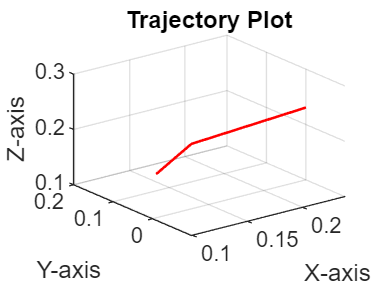

figure
plot3(ee_positions(1, :),ee_positions(2, :),ee_positions(3, :),'r', 'LineWidth', 1);
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('Trajectory Plot');
grid on;

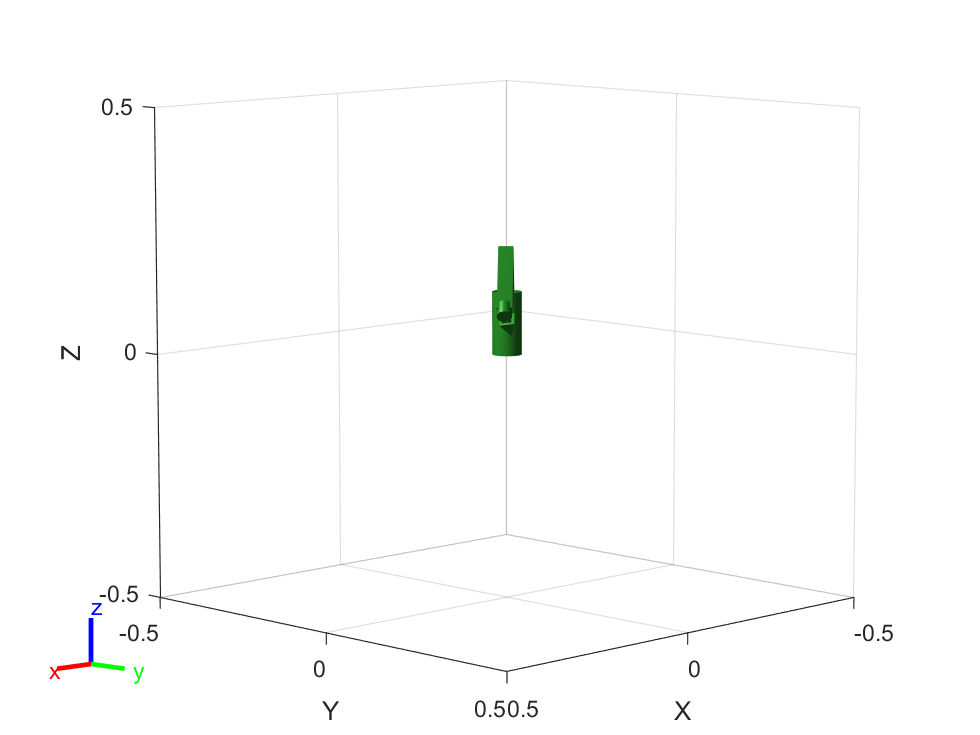

%% Robot Simulation & Creating Video
Initial = homeconfig;
Step = 1;
framesPerSecond = 30;
cnt = 1;
for j = 2 : length(theta_list)
    Qd = theta_list(:,j) - theta_list(:,j-1);
    for i = 1:Step
        q = theta_list(:,j-1) + Qd / Step * i;
        show(robot,q,"Collisions","on","Frames","off");

        F(cnt) = getframe(gcf) ;
        cnt = cnt+1;
        drawnow
    end
end


% create the video writer with 1 fps
writerObj = VideoWriter('Task3.avi');
writerObj.FrameRate = 10;
% set the seconds per image
% open the video writer
open(writerObj);
% write the frames to the video
for i=1:length(F)
    % convert the image to a frame
    frame = F(i) ;    
    writeVideo(writerObj, frame);
end
% close the writer object
close(writerObj);

joint_positions = theta_list

joint_positions =          0   -0.0139   -0.0284   -0.0435   -0.0592   -0.0755   -0.0924   -0.1101   -0.1285   -0.1477   -0.1676   -0.1884   -0.2100   -0.2326   -0.2560   -0.2804   -0.3058   -0.3322   -0.3596   -0.3881   -0.4176   -0.4482   -0.4798   -0.5125   -0.5462   -0.5808   -0.6164   -0.6529   -0.6902   -0.7283   -0.7670   -0.7349   -0.7016   -0.6671   -0.6315   -0.5947   -0.5568   -0.5178   -0.4779   -0.4372   -0.3957   -0.3537   -0.3111   -0.2683   -0.2253   -0.1823   -0.1395   -0.0970   -0.0550   -0.0136
   -1.1676   -1.2081   -1.2479   -1.2869   -1.3253   -1.3630   -1.4001   -1.4364   -1.4721   -1.5072   -1.5415   -1.5750   -1.6078   -1.6397   -1.6708   -1.7009   -1.7300   -1.7580   -1.7848   -1.8105   -1.8348   -1.8577   -1.8791   -1.8990   -1.9172   -1.9338   -1.9485   -1.9614   -1.9724   -1.9815   -1.9885   -2.0180   -2.0462   -2.0730   -2.0983   -2.1220   -2.1440   -2.1642   -2.1823   -2.1982   -2.2118   -2.2229   -2.2312   -2.2367   -2.2392   -2.2384   -2.2344   -2.2269 

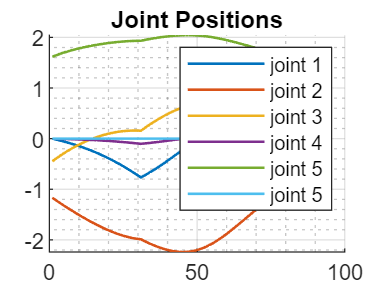

figure;
grid on;
grid minor;
hold on;
for i = 1:6
    %subplot(6, 1, i);
    plot(joint_positions(i,:),'LineWidth',1);
end
title("Joint Positions");
legend('joint 1','joint 2','joint 3','joint 4','joint 5','joint 5');
hold off;

figure;
joint_positions = theta_list

joint_positions =          0   -0.0139   -0.0284   -0.0435   -0.0592   -0.0755   -0.0924   -0.1101   -0.1285   -0.1477   -0.1676   -0.1884   -0.2100   -0.2326   -0.2560   -0.2804   -0.3058   -0.3322   -0.3596   -0.3881   -0.4176   -0.4482   -0.4798   -0.5125   -0.5462   -0.5808   -0.6164   -0.6529   -0.6902   -0.7283   -0.7670   -0.7349   -0.7016   -0.6671   -0.6315   -0.5947   -0.5568   -0.5178   -0.4779   -0.4372   -0.3957   -0.3537   -0.3111   -0.2683   -0.2253   -0.1823   -0.1395   -0.0970   -0.0550   -0.0136
   -1.1676   -1.2081   -1.2479   -1.2869   -1.3253   -1.3630   -1.4001   -1.4364   -1.4721   -1.5072   -1.5415   -1.5750   -1.6078   -1.6397   -1.6708   -1.7009   -1.7300   -1.7580   -1.7848   -1.8105   -1.8348   -1.8577   -1.8791   -1.8990   -1.9172   -1.9338   -1.9485   -1.9614   -1.9724   -1.9815   -1.9885   -2.0180   -2.0462   -2.0730   -2.0983   -2.1220   -2.1440   -2.1642   -2.1823   -2.1982   -2.2118   -2.2229   -2.2312   -2.2367   -2.2392   -2.2384   -2.2344   -2.2269 

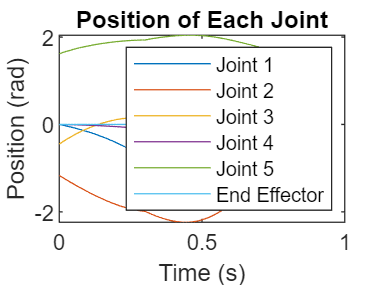

plot(0:0.01:0.80, joint_positions);
title("Position of Each Joint");
xlabel("Time (s)");
ylabel("Position (rad)");
legend('Joint 1', 'Joint 2', 'Joint 3', 'Joint 4', 'Joint 5', 'End Effector');

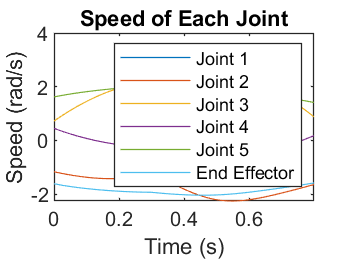



% Calculate speed
speedMatrix = diff(theta_list) ./ diff((1:size(theta_list, 1))');
speedMatrix = [NaN(1, size(theta_list, 2)); speedMatrix];

figure
plot(0:0.01:0.8,speedMatrix);
title("Speed of Each Joint");
xlabel("Time (s)");
ylabel("Speed (rad/s)");
legend('Joint 1', 'Joint 2', 'Joint 3', 'Joint 4', 'Joint 5', 'End Effector');

% dt = 1;
% joint_velocities = diff(theta_list)/dt;
% joint_velocities = [joint_velocities; zeros(1,length(joint_velocities))];
% figure;
% grid on;
% grid minor;
% hold on;
% for i = 1:6
%     %subplot(6, 1, i);
%     plot(joint_velocities(i,:),'LineWidth',1);
% end
% title("Joint Velocities");
% legend('joint 1','joint 2','joint 3','joint 4','joint 5','joint 5');
% hold off;

Task3_theta_list = theta_list;
Task3_theta_list(2,:) = Task3_theta_list(2,:) + pi/2;
Task3_theta_list(5,:) = Task3_theta_list(5,:) - pi/2;
save("Task3_theta_list.mat","Task3_theta_list");

function to split the path

function target_points = split_target_points(p_init,p_target,p_number)
target_points = zeros(3,p_number+1);
Vp_to_target = p_target-p_init; % total vector from guessed position to desired target position 
delta_p = Vp_to_target/p_number;
target_points(:,1) = p_init;
for i = 2:p_number+1
    target_points(:,i) = target_points(:,i-1)+delta_p;
end
end

function to calculate transform matrix according to one line of the MDH table

function T = dh_transmatrix(a,alpha,d,theta)
    T = [   cos(theta),             -sin(theta),            0,           a;
            sin(theta)*cos(alpha),  cos(theta)*cos(alpha), -sin(alpha), -sin(alpha)*d;
            sin(theta)*sin(alpha),  cos(theta)*sin(alpha),  cos(alpha),  cos(alpha)*d;
            0,                      0,                      0,           1];
end